clear;clc;close all;
warning('off');
root_path = "D:\Document\EasyLM_RSBA\";
addpath(genpath(root_path))

% -------------- system config --------------
param.scale = 13;
param.measurement_noise = 1.1;
param.num_camera = 7;
param.H = 1080; % height of image in pixels
param.W = 1280; % width of image in pixels
param.fx = 1000; % focal length in pixels
param.fy = 1000; % focal length in pixels
param.cx = 640; % optical center
param.cy = 540;
param.K_matrix = [ param.fx 0 param.cx ; % Intrinsic camera parameter matrix
    0 param.fy param.cy ;
    0 0 1 ];
param.t_v = 0.00004625;
param.w_norm = 150;
param.d_norm = 10;
param.pitch = 0.01;
%param.pitch = 0.3;
param.num_error_of_line = 12;  %num points in the line
param.have_points = 0;
param.is_error_p = 1;
param.is_error_l = 0;
format long;



% -------------- generate camera param -------------
initialized_flag = false;
while ~initialized_flag
    try
        %[camera_set, point_set, line_set, param, flag] = rs_simulate_line(param);
        [camera_set, point_set, line_set, param, flag] = rs_simulate_line_degeneracy(param);
        [camera_normal_set, param] = rs_simulate_normal(camera_set, param);

        if flag == 1
            disp('wd too large or scale too small');
            continue;
        end

        initialized_flag = true;
        disp('initialization success');

        % ------ get state vector ------
        gt_state_vector = raw2vec(camera_set, point_set, param, true);
        initial_state_vector = raw2vec(camera_set, point_set, param, false);
        gt_normal_state_vector = raw2vec(camera_normal_set, point_set, param, true);
        initial_normal_state_vector = raw2vec(camera_normal_set, point_set, param, false);
        % ------ get normalized state vector ------
        gt_state_vector_line = raw2vec_line(camera_set, point_set, line_set, param, true);
        initial_state_vector_line = raw2vec_line(camera_set, point_set, line_set, param, false);
        gt_normal_state_vector_line = raw2vec_line(camera_normal_set, point_set, line_set, param, true);
        initial_normal_state_vector_line = raw2vec_line(camera_normal_set, point_set, line_set, param, false);
    catch
        disp('initialization fail error!!!');
        continue;
    end
end

initialization success



% -------------- gsba --------------
refined_state_vector = gsba_easylm_solver(camera_set, initial_state_vector, param);
[refined_state_vector, scale] = AdjustWithScale(refined_state_vector, gt_state_vector, param);
[point_error_norm_gs, r_error_norm_gs, t_error_norm_gs, w_error_norm_gs, d_error_norm_gs] = CalculatePramError(refined_state_vector, gt_state_vector, param);
output_gs = sprintf([ ...
    'points_error: %.8f\n' ...
    'R_error: %.8f\n' ...
    't_error: %.8f\n'], ...
    point_error_norm_gs, r_error_norm_gs, t_error_norm_gs);
disp(output_gs);

points_error: 0.28248043
R_error: 0.01254751
t_error: 0.96715396



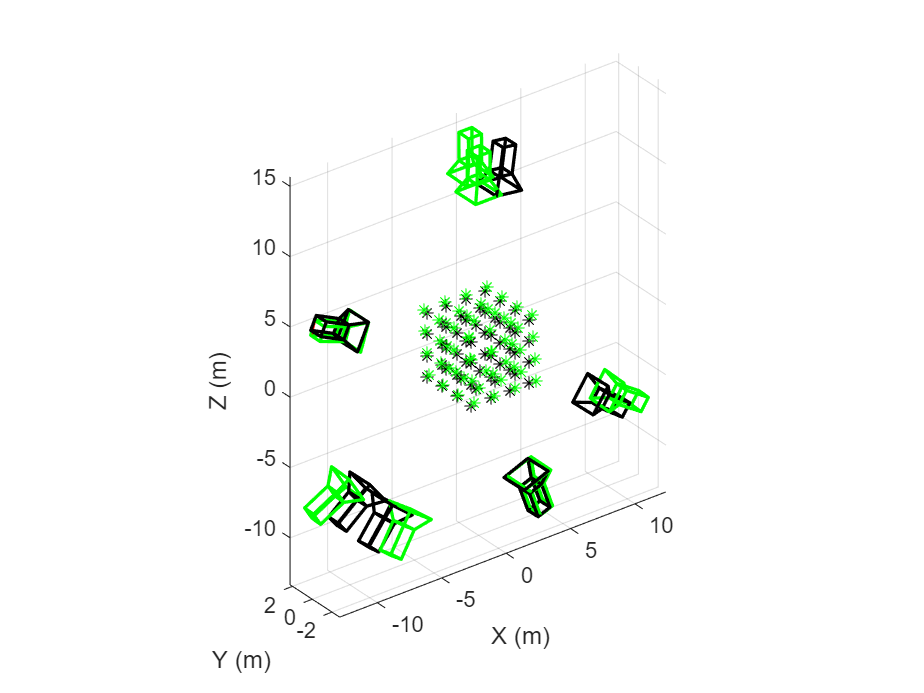

plot_cell = cell(1,3);
plot_gt.camera_state_vector = gt_state_vector;
plot_gt.point_state_vector = point_set.point_gt;
plot_gt.color = "black";
plot_cell{1, 1} = plot_gt;
plot_gt.camera_state_vector = initial_state_vector;
plot_gt.point_state_vector = point_set.point;
plot_gt.color = "red";
plot_cell{1, 2} = plot_gt;
point = getPoint(refined_state_vector, param);
plot_gt.camera_state_vector = refined_state_vector;
plot_gt.point_state_vector = point;
plot_gt.color = "green";
plot_cell{1, 3} = plot_gt;
plot3d_rs(plot_cell, param);


% %  % -------------- nmrsba --------------
refined_state_vector = nmrsba_easylm_solver(camera_set, initial_state_vector, param);
[refined_state_vector, scale] = AdjustWithScale(refined_state_vector, gt_state_vector, param);
[point_error_norm_mrs, r_error_norm_mrs, t_error_norm_mrs, w_error_norm_mrs, d_error_norm_mrs] = CalculatePramError(refined_state_vector, gt_state_vector, param);
output_nmrs = sprintf([ ...
    'points_error: %.8f\n' ...
    'R_error: %.8f\n' ...
    't_error: %.8f\n'], ...
    point_error_norm_mrs, r_error_norm_mrs, t_error_norm_mrs);

disp(output_nmrs);

points_error: 0.72400461
R_error: 0.00654882
t_error: 0.05865595



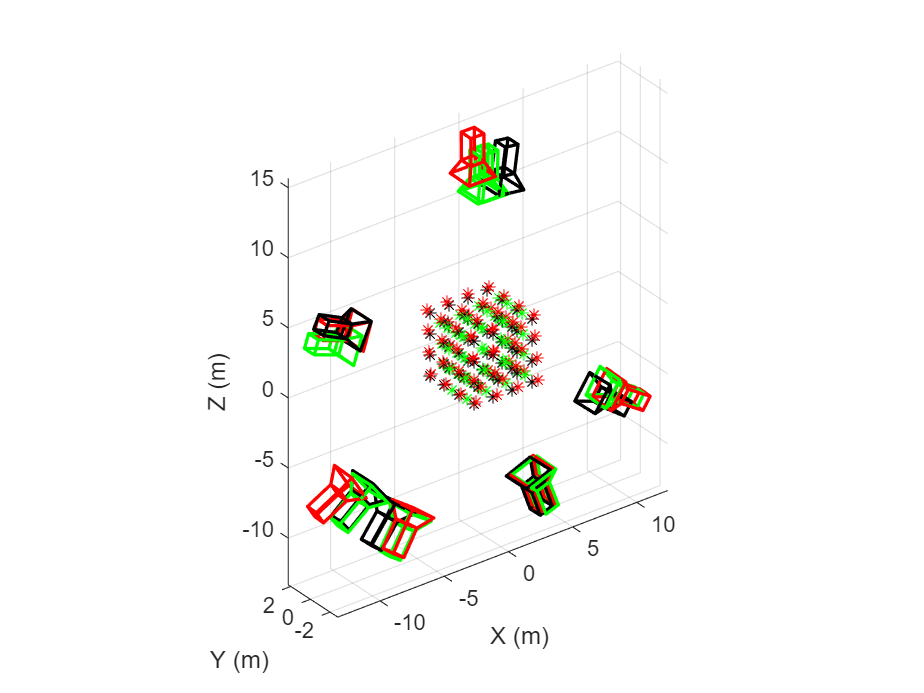

xqplot_cell = cell(1,3);
plot_gt.camera_state_vector = gt_state_vector;
plot_gt.point_state_vector = point_set.point_gt;
plot_gt.color = "black";
plot_cell{1, 1} = plot_gt;
plot_gt.camera_state_vector = initial_state_vector;
plot_gt.point_state_vector = point_set.point;
plot_gt.color = "red";
plot_cell{1, 2} = plot_gt;
point = getPoint(refined_state_vector, param);
plot_gt.camera_state_vector = refined_state_vector;
plot_gt.point_state_vector = point;
plot_gt.color = "green";
plot_cell{1, 3} = plot_gt;
plot3d_rs(plot_cell, param);


% %  % -------------- nwrsba --------------
refined_state_vector = nwrsba_easylm_solver(camera_set, initial_normal_state_vector, param);
[refined_state_vector, scale] = AdjustWithScale(refined_state_vector, gt_normal_state_vector, param);
[point_error_norm_nwrs, r_error_norm_nwrs, t_error_norm_nwrs, w_error_norm_nwrs, d_error_norm_nwrs] = CalculatePramError(refined_state_vector, gt_normal_state_vector, param);
output_nwrs = sprintf([ ...
    'points_error: %.8f\n' ...
    'R_error: %.8f\n' ...
    't_error: %.8f\n'], ...
    point_error_norm_nwrs, r_error_norm_nwrs, t_error_norm_nwrs);

disp(output_nwrs);

points_error: 0.03509254
R_error: 0.00004407
t_error: 0.00108146



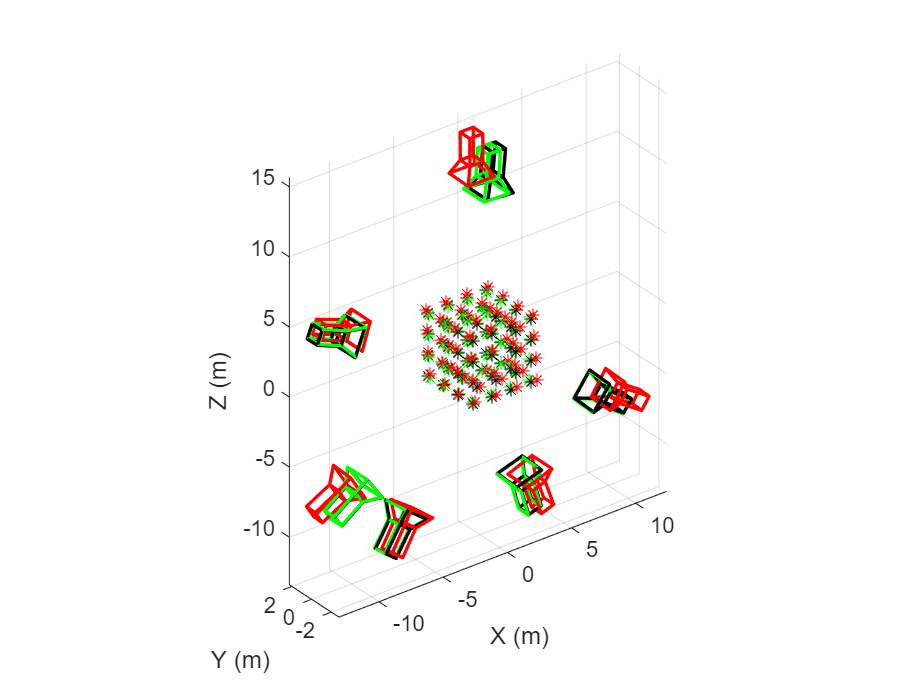

plot_cell = cell(1,3);
plot_gt.camera_state_vector = gt_normal_state_vector;
plot_gt.point_state_vector = point_set.point_gt;
plot_gt.color = "black";
plot_cell{1, 1} = plot_gt;
plot_gt.camera_state_vector = initial_normal_state_vector;
plot_gt.point_state_vector = point_set.point;
plot_gt.color = "red";
plot_cell{1, 2} = plot_gt;
point = getPoint(refined_state_vector, param);
plot_gt.camera_state_vector = refined_state_vector;
plot_gt.point_state_vector = point;
plot_gt.color = "green";
plot_cell{1, 3} = plot_gt;
plot3d_rs(plot_cell, param);


%  % -------------- nlgs --------------
param.rs_line_ba = 2;
param.have_points = 0;
param.is_error_p = 0;
param.is_error_l = 1;
refined_state_vector = nlgsba_easylm_solver(camera_set, initial_normal_state_vector_line , param);
[refined_state_vector, scale] = AdjustWithScale(refined_state_vector, gt_normal_state_vector_line, param);
[point_error_norm_nlgs, r_error_norm_nlgs, t_error_norm_nlgs, w_error_norm_nlgs, d_error_norm_nlgs, l_r_error_norm_nlgs, l_d_error_norm_nlgs] = CalculatePramError(refined_state_vector, gt_normal_state_vector_line, param);
output_nlgs = sprintf([ ...
    'R_error: %.8f\n' ...
    't_error: %.8f\n' ...
    'l_R_error: %.8f\n' ...
    'l_d_error: %.8f\n'], ...
    r_error_norm_nlgs, t_error_norm_nlgs, l_r_error_norm_nlgs, l_d_error_norm_nlgs);

disp(output_nlgs);

R_error: 0.01078666
t_error: 0.51125522
l_R_error: 0.08990870
l_d_error: 0.01803566



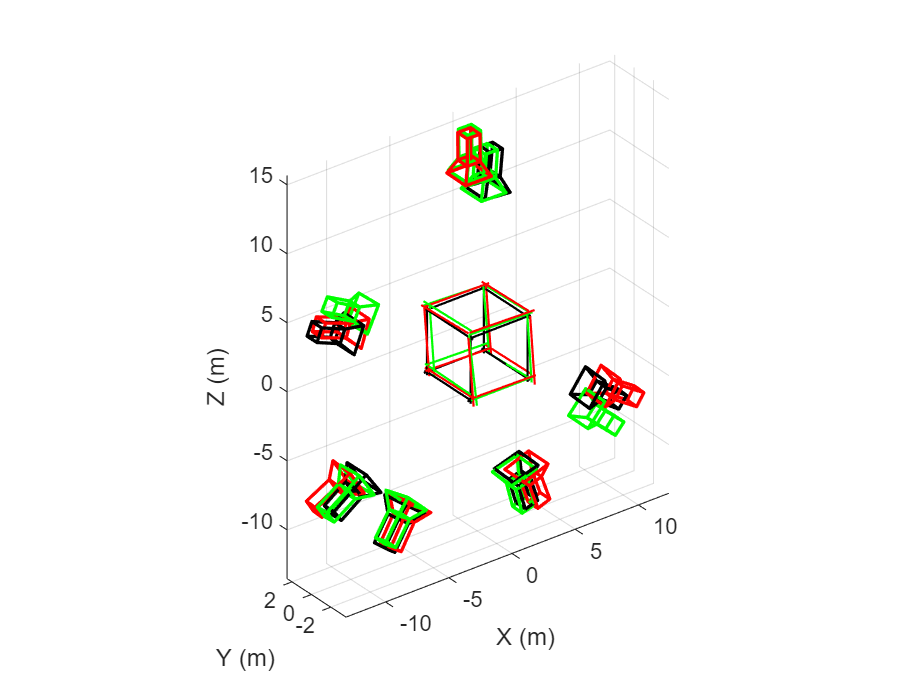

plot_cell = cell(1,3);
plot_gt.camera_state_vector = gt_normal_state_vector_line;
plot_gt.line_state_vector = line_set.line_gt;
plot_gt.color = "black";
plot_cell{1, 1} = plot_gt;
plot_gt.camera_state_vector = initial_normal_state_vector_line;
plot_gt.line_state_vector = line_set.line;
plot_gt.color = "red";
plot_cell{1, 2} = plot_gt;
line = getLine(refined_state_vector, param);
plot_gt.camera_state_vector = refined_state_vector;
plot_gt.line_state_vector = line;
plot_gt.color = "green";
plot_cell{1, 3} = plot_gt;
plot3d_line_rs(plot_cell, param);

%  % -------------- nslrsba --------------
param.rs_line_ba = 2;
param.have_points = 0;
param.is_error_p = 0;
param.is_error_l = 1;
refined_state_vector = nslrsba_easylm_solver(camera_set, initial_normal_state_vector_line , param);
[refined_state_vector, scale] = AdjustWithScale(refined_state_vector, gt_normal_state_vector_line, param);
[point_error_norm_nlrs, r_error_norm_nlrs, t_error_norm_nlrs, w_error_norm_nlrs, d_error_norm_nlrs, l_r_error_norm_nlrs, l_d_error_norm_nlrs] = CalculatePramError(refined_state_vector, gt_normal_state_vector_line, param);
output_nslrs = sprintf([ ...
    'R_error: %.8f\n' ...
    't_error: %.8f\n' ...
    'l_R_error: %.8f\n' ...
    'l_d_error: %.8f\n'], ...
    r_error_norm_nlrs, t_error_norm_nlrs, l_r_error_norm_nlrs, l_d_error_norm_nlrs);

disp(output_nslrs);

R_error: 0.00001815
t_error: 0.00063058
l_R_error: 0.01284176
l_d_error: 0.00061074



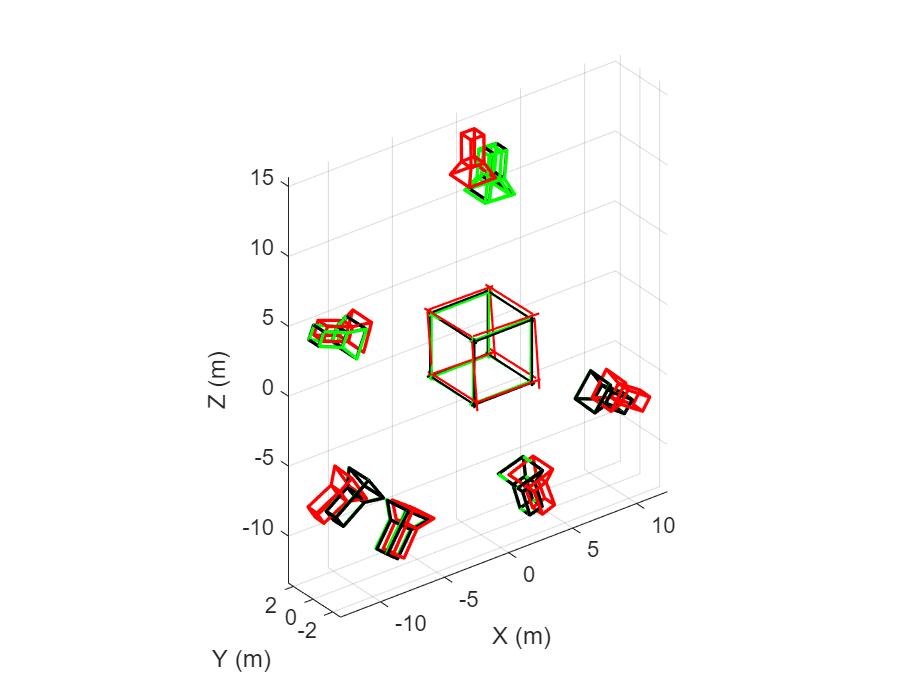


plot_cell = cell(1,3);
plot_gt.camera_state_vector = gt_normal_state_vector_line;
plot_gt.line_state_vector = line_set.line_gt;
plot_gt.color = "black";
plot_cell{1, 1} = plot_gt;
plot_gt.camera_state_vector = initial_normal_state_vector_line;
plot_gt.line_state_vector = line_set.line;
plot_gt.color = "red";
plot_cell{1, 2} = plot_gt;
line = getLine(refined_state_vector, param);
plot_gt.camera_state_vector = refined_state_vector;
plot_gt.line_state_vector = line;
plot_gt.color = "green";
plot_cell{1, 3} = plot_gt;
plot3d_line_rs(plot_cell, param);





% ----------- gsba -----------
function refined_state_vector = gsba_easylm_solver(camera_set, initial_state_vector, param)
cam_oth = initial_state_vector(1, 1:param.num_camera*6);
for i = 1:param.num_camera
    id = (i - 1) * 12 + 1;
    id_c = (i - 1) * 6 + 1;
    cam_oth(1, id_c:id_c + 5) = initial_state_vector(1, id:id + 5);
end
cam_oth = [cam_oth initial_state_vector(1, 12 * param.num_camera + 1:end)];
solver = EasyLM(@(x)fj_gsba_opter(x, camera_set, param), @(x, dx)so3_gsba_update_func(x, dx, param), 'SpecifyObjectiveGradient', true, 'FixParameter', [1 2 3 4 5 6]);
refined_state_vector = solver.solve(cam_oth);

tmp_x = initial_state_vector(1, 1:param.num_camera*12);
point = refined_state_vector(param.num_camera * 6 + 1:end);
for i = 1:param.num_camera
    id_c = (i - 1) * 6 + 1;
    id = (i - 1) * 12 + 1;
    tmp_x(1, id:id + 5) = refined_state_vector(1, id_c:id_c + 5);
end
refined_state_vector = [tmp_x point];
end





% ----------- nwrsba -----------
function refined_state_vector = nwrsba_easylm_solver(camera_set, initial_normal_state_vector, param)
solver = EasyLM(@(x)fj_nwrsba_opter(x, camera_set, param), @(x, dx)euc_update_func(x, dx), 'SpecifyObjectiveGradient', true, 'FixParameter', [1 2 3 4 5 6]);
refined_state_vector = solver.solve(initial_normal_state_vector);
end


% ----------- nslrsba -----------
function refined_state_vector = nslrsba_easylm_solver(camera_set, initial_state_vector, param)
solver = EasyLM(@(x)fj_nslrsba_opter(x, camera_set, param), @(x, dx)so3_rsba_update_func(x, dx, param), 'SpecifyObjectiveGradient', true, 'FixParameter', [1 2 3 4 5 6]);
refined_state_vector = solver.solve(initial_state_vector);
end


% ----------- nmrsba -----------
function refined_state_vector = nmrsba_easylm_solver(camera_set, initial_normal_state_vector, param)
    solver = EasyLM(@(x)fj_nmrsba_opter(x, camera_set, param), @(x, dx)so3_rsba_update_func(x, dx, param), 'SpecifyObjectiveGradient', true, 'FixParameter', [1 2 3 4 5 6]);
    refined_state_vector = solver.solve(initial_normal_state_vector);
end

% ----------- nlgsba -----------
function refined_state_vector = nlgsba_easylm_solver(camera_set, initial_state_vector, param)
cam_oth = initial_state_vector(1, 1:param.num_camera*6);
for i = 1:param.num_camera
    id = (i - 1) * 12 + 1;
    id_c = (i - 1) * 6 + 1;
    cam_oth(1, id_c:id_c + 5) = initial_state_vector(1, id:id + 5);
end
cam_oth = [cam_oth initial_state_vector(1, 12 * param.num_camera + 1:end)];
solver = EasyLM(@(x)fj_nlgsba_opter(x, camera_set, param), @(x,dx)euc_update_func(x, dx), 'SpecifyObjectiveGradient', true, 'FixParameter', [1 2 3 4 5 6]);
refined_state_vector = solver.solve(cam_oth);

tmp_x = initial_state_vector(1, 1:param.num_camera*12);
point = refined_state_vector(param.num_camera * 6 + 1:end);
for i = 1:param.num_camera
    id_c = (i - 1) * 6 + 1;
    id = (i - 1) * 12 + 1;
    tmp_x(1, id:id + 5) = refined_state_vector(1, id_c:id_c + 5);
end
refined_state_vector = [tmp_x point];
end

